### **Communication Systems Laboratory**

**Lab 4: OFDM Transmission Using USRP**

**Students: **B11901006 臧逸新、B11901013 俞柏安、B11901101 謝函蓁

#### Wifi-Modulation Initialize

% clc; clear; close all;

% Required Files:
% 'single_100.mat'
% 'sig_5.mat'
% 'different_CFOs.mat'


%---------Re-generate signal option------%
% 0 for using stored signal 
% 1 for regenerating signal 
REGEN_SIG_FLAG_5 = 0;
REGEN_SIG_FLAG_100_multi = 0; 
REGEN_SIG_FLAG_100_single = 0; 
RE_RECEIVE_DIFFERENT_CFO = 0;
%----------------------------------------%
global pilot_idx;
global data_idx;
global zero_idx;
global channel_est
global N_FFT;
global N_CP;
global fs;
global ts;
global fc;
%% Parameters
N_FFT = 64;  % FFT size
N_CP = 16;   % Cyclic prefix length
N_OFDM = N_FFT+N_CP; 
fs = 10e6;   % Sampling rate (Hz)
ts = 1/fs;   % Sampling time
fc = 915e6;  % Carrier frequency (Hz)


% Define subcarrier indices for 802.11a/g
pilot_idx = [12 26 40 54];   % Pilot subcarriers (1-based index)
data_idx = setdiff(1:N_FFT, [1:6, pilot_idx, N_FFT/2+1, 1:6, 60:64]); % Exclude DC, pilot, and unused guard bands
zero_idx = [1:6, N_FFT/2+1, 60:64];

% 5- OFDM symbols with STS, LTS;
L_sig_5_head = 320;
L_sig_5 =  L_sig_5_head + 5 * (N_OFDM);
L_sig_100   = L_sig_5_head + 100 * (N_OFDM);

% scaling of transmitted amplitude
send_amp = 0.1;

% color style
% '#003C76': Deep Blue
% '#939880': Tea Green
% '#875B75': Plum Purple
% '#DAC1AE': Skin Pink
% '#99755A': Brown
% '#393939': Black

#### **Funcion Definition**

% generate single OFDM symbol
function ofdm_SYM = ofdm_generate(mod_size)
    %% Generate pilot tones (BPSK modulation)
    global pilot_idx;
    global data_idx;
    global N_FFT

    pilot_bits = [1, 1, 1, -1];
    X_pilot = pilot_bits + 0j; % Convert to complex symbols
    
    %% Generate data tones (16-QAM modulation)
    data_bits = randi([0 mod_size - 1], length(data_idx), 1); % Random 16-QAM symbols
    qam_mod = qammod(data_bits, mod_size, 'UnitAveragePower', true);

    %% Create OFDM symbol in frequency domain
    ofdm_SYM = zeros(N_FFT, 1);
    ofdm_SYM(data_idx) = qam_mod;  % Assign 4-QAM data
    ofdm_SYM(pilot_idx) = X_pilot; % Assign BPSK pilot tones
end


function X_shifted = ofdm_shift(X)
    % global N_FFT; global fs;
    % freq_vector = (-N_FFT/2:N_FFT/2-1) * (fs/N_FFT); % Frequency in MHz
    % fv = exp(-2*j*pi*(freq_vector)).';
    % X_shifted = X .* fv;
    X_shifted = X;
end

function X_ishifted = ofdm_ishift(X)
    global N_FFT; global fs;
    freq_vector = (-N_FFT/2:N_FFT/2-1) * (fs/N_FFT); % Frequency in MHz
    fv = exp(-2*j*pi*(freq_vector)).';
    X_ishifted = X ./ fv;
end

% add time-domain cyclic prefix for a single symbol
function sig_b = ofdm_addCP(sig_a)
    global N_FFT; global N_CP;
    sig_b = zeros(N_FFT + N_CP, 1);
    cyclic_prefix = sig_a(N_FFT-N_CP+1:end);
    sig_b(1:N_CP) = cyclic_prefix;
    sig_b(N_CP+1:end) = sig_a;
end

% remove time-domain cyclic prefix for a single symbol
function sig_c = ofdm_removeCP(sig_b)
    global N_CP;
    sig_c = sig_b(N_CP+1:end);
end

% generate a complete normalized STS 
function [STS, single_STS] = STS_generate()
    global N_FFT;
    STS_values = sqrt(13/6) * [0, 0, 1+1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, -1-1j, ...
                                0, 0, 0, -1-1j, 0, 0, 0, 1+1j, 0, 0, 0, 0, 0, 0, 0, ...
                                -1-1j, 0, 0, 0, -1-1j, 0, 0, 0, 1+1j, ...
                               0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0, 0, 1+1j, 0, 0];
    
    single_STS = zeros(N_FFT, 1);
    single_STS(7:59) = STS_values;
    
    x_single_sts = ifft(ifftshift(ofdm_shift(single_STS)));
    
    STS = zeros(length(x_single_sts)*2.5, 1);
    STS(1:N_FFT/2) = x_single_sts(N_FFT/2+1:end);
    for i = 0:1
        STS(i*length(x_single_sts)+ N_FFT/2+1 : (i+1)*length(x_single_sts)+ N_FFT/2) = x_single_sts;
    end
    single_STS = STS(1:16);
    STS = STS / mean(abs(STS));
end

% generate a complete normalized LTS
function [LTS, single_LTS] = LTS_generate()
    global N_FFT;
    LTS_values = [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1, ...
        -1, -1, 1, 1, -1, 1,-1, 1,-1,-1,-1,-1,-1, 1, 1,-1,-1, 1,-1,1,-1,1,1,1,1];
    
    single_LTS = zeros(N_FFT, 1);
    single_LTS(7:59) = LTS_values;
    
    x_single_lts = ifft(ifftshift(ofdm_shift(single_LTS))); % time domain
    
    LTS = zeros(length(x_single_lts)*2.5, 1);
    LTS(1:N_FFT/2) = x_single_lts(N_FFT/2+1:end);
    for i = 0:1
        LTS(i*length(x_single_lts)+ N_FFT/2 +1 : (i+1)*length(x_single_lts)+ N_FFT/2 ) = x_single_lts;
    end
    
    LTS = LTS / mean(abs(LTS));
end



**(1)** Generate a frame with STS, LTS, and 5 OFDM symbols using 4-QAM modulation for the data tones. Pre-pad and post-pad the frame with 100 zeros (100 zeros, STS, LTS, 5 OFDM symbols, 100 zeros). Plot the generated frame in the time domain with the correct time unit in microseconds. Please mark the STS, LTS, and data symbols. Notice that the sampling rate of the USRP is 10 MHz, which is different from the sampling rate of 20 MHz in Lab 3, and thus the frame duration is different.

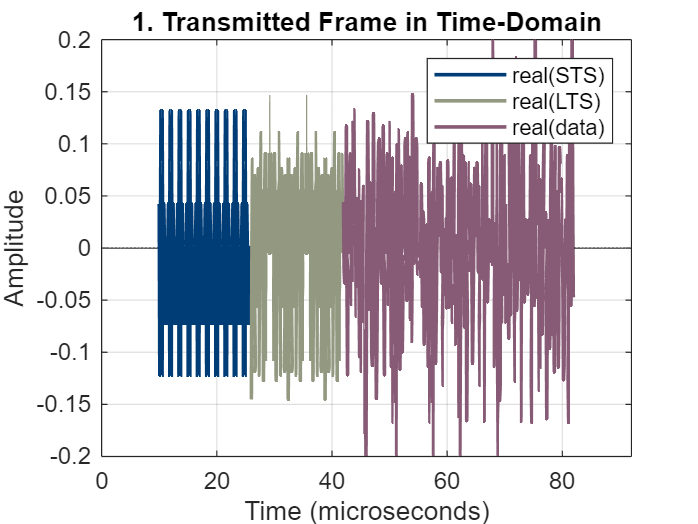

sig_5 = zeros(L_sig_5, 1);

if REGEN_SIG_FLAG_5 == 0
    load('sig_5.mat');

elseif REGEN_SIG_FLAG_5 == 1
    %% (1) Compute and plot magnitude spectrum
    [STS, single_STS] = STS_generate();
    [LTS, single_LTS] = LTS_generate();
    single_LTS = LTS(end-64+1:end);
    
    % pre-save data_bits
    data_tx = zeros(5*48, 1);
    
    % generate 5 OFDM Symbols
    for i = 0:4
        X = ofdm_generate(4); % generate single OFDM symbol
        X_shifted = ofdm_shift(X); 
        sig_a = ifft(ifftshift(X_shifted));
        x_cp = ofdm_addCP(sig_a);
        data_tx(48*i+1 : 48*(i+1)) = X(data_idx);
        sig_5(L_sig_5_head + i*(N_OFDM)+1 : L_sig_5_head+(i+1)*(N_OFDM)) = x_cp;
    end
    sig_5(L_sig_5_head+1:end) = sig_5(L_sig_5_head+1:end)/mean(abs(sig_5(L_sig_5_head+1:end)));
    
    sig_5(1:length(STS)) = STS;
    sig_5(length(STS)+1:length(STS)+length(LTS) )= LTS;
    bits_tx = qamdemod(data_tx, 4, 'gray', OutputType='bit', UnitAveragePower=true);
    
end

padded_sig_5 = send_amp*[zeros(100, 1); sig_5; zeros(100, 1)];
time_vector = (0:L_sig_5+200-1) * ts * 1e6; % Time in microseconds

close all;
figure;
p0 = plot(time_vector(1:100), ...
    real(padded_sig_5(1:100)), 'k');
hold on;
p1 = plot(time_vector(100+1             :100+length(STS)), ...
    real(padded_sig_5(100+1             :100+length(STS))), 'Color', '#003C76', 'LineWidth', 1.5);
p2 = plot(time_vector(100+length(STS)+1 :100+L_sig_5_head), ...
    real(padded_sig_5(100+length(STS)+1 :100+L_sig_5_head) ),'Color', '#939880', 'LineWidth', 1.5);
p3 = plot(time_vector(100+L_sig_5_head+1:end-100), ...
    real(padded_sig_5(100+L_sig_5_head+1:end-100)),'Color', '#875B75', 'LineWidth', 1.5);
p4 = plot(time_vector(end-100+1         :end), ...
    real(padded_sig_5(end-100+1         :end)), 'k');

xlabel('Time (microseconds)'); ylabel('Amplitude');
axis([0 92 -0.2 0.2])
title('1. Transmitted Frame in Time-Domain');
legend([p1(1), p2(1), p3(1)],'real(STS)', 'real(LTS)','real(data)');
grid on;
hold off;

**(2)** Transmit the frame generated in (1). Plot the received frame in the time domain with the correct time unit in microseconds. As in (1), please mark the STS, LTS, and data symbols. Please make sure the received signal is of proper signal strength – it should not show signs of clipping, and the signal can be easily distinguishable from the zeros. 

close all;
addpath("./test_code/")

if REGEN_SIG_FLAG_5 == 1
    
    l = length(padded_sig_5);
    [radio_Tx,radio_Rx] = USRP_init(l);
    buffer = zeros(30*l, 1);
    
    % Transmit the frame we generate
    
    % Transmit 15 zero frames 
    % (Otherwise there will be no output.) 
    % (I not yet know why this bug happens.)
    for ii = 1:20
        if ii == 1
            tunderrun = radio_Tx(padded_sig_5);
        else
            tunderrun = radio_Tx(zeros(l, 1));
        end
        % step(radio_Rx);
        [rcvdSignal, ~, toverflow] = step(radio_Rx);
        buffer((1+(ii-1)*l):(ii*l)) = rcvdSignal;
    end
    
    % Keep reception for 15 frames 
    for ii = 21 : 30
        [rcvdSignal, ~, toverflow] = step(radio_Rx);
        buffer((1+(ii-1)*l):(ii*l)) = rcvdSignal;
    end 
    
    % To save new data, uncomment this line. 
    % Otherwise, keep it commented so that rx_sig.mat won't be modified.
    % save rx_sig.mat buffer
    
    release(radio_Tx)
    release(radio_Rx)
end


figure:

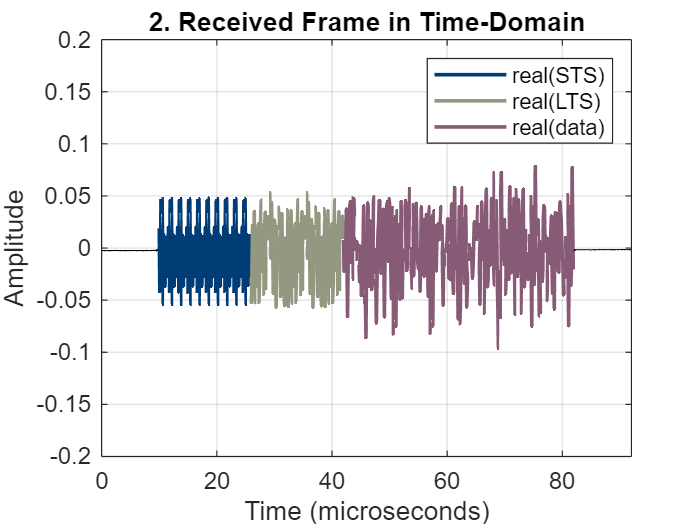

close all;

function [sec_beg, sec_end] = trim_buffer(buffer, plot_len, sec_blank)

    sec_beg = 1;
    cur_sum = 0;
    for ii = 1 : length(buffer)-plot_len+1
        if cur_sum < sum(abs(buffer(ii:ii+plot_len-1)))
            cur_sum = sum(abs(buffer(ii:ii+plot_len-1)));
            sec_beg = ii;
        end
    end
    sec_beg = max(1, sec_beg - sec_blank);
    
    sec_end = sec_beg + plot_len + 2*sec_blank;
end
%----------------------------

% find where the signal starts
plot_len = 720;  % 要取多長平均
sec_blank = 100; % 兩邊留多長
[sec_beg, sec_end] = trim_buffer(buffer, plot_len, sec_blank);
sig_5_rx = buffer(sec_beg:sec_end-1);
time_vector = (0:L_sig_5+200-1) * ts * 1e6; % Time in microseconds

figure;
p0 = plot(time_vector(1:100), ...
    real(sig_5_rx(1:100)), 'k');
hold on;
p1 = plot(time_vector(100+1             :100+length(STS)), ...
        real(sig_5_rx(100+1             :100+length(STS))), 'Color', '#003C76', 'LineWidth', 1.5);
p2 = plot(time_vector(100+length(STS)+1 :100+L_sig_5_head), ...
        real(sig_5_rx(100+length(STS)+1 :100+L_sig_5_head) ),'Color', '#939880', 'LineWidth', 1.5);
p3 = plot(time_vector(100+L_sig_5_head+1:end-100), ...
        real(sig_5_rx(100+L_sig_5_head+1:end-100)),'Color', '#875B75', 'LineWidth', 1.5);
p4 = plot(time_vector(end-100+1         :end), ...
        real(sig_5_rx(end-100+1         :end)), 'k');

xlabel('Time (microseconds)'); ylabel('Amplitude');
axis([0 92 -0.2 0.2])
title('2. Received Frame in Time-Domain');
legend([p1(1), p2(1), p3(1)],'real(STS)', 'real(LTS)','real(data)');
grid on;
hold off;

**(3) **Apply the frame synchronization algorithm you designed in Lab 3 to identify the correct beginning of the OFDM symbols. Please plot the match filter result.

function [lts_start, ofdm_start] = LTS_CONV(buffer_trimmed,sec_beg, single_LTS)
    conv_sig_LTS = conv(buffer_trimmed, flipud(conj(single_LTS)), "valid"); % inden range should be adjusted
    % figure;
    % plot(abs(conv_sig_LTS))
    % hold off;
    crit_lts = max(abs(conv_sig_LTS))-0.3;
    lts_peaks = find(abs(conv_sig_LTS) >= crit_lts);
    lts_start = sec_beg + lts_peaks(1)-1;
    ofdm_start = lts_start + 2*64;
end
close all;


% convolve with received signal (buffer)

[lts_start, ofdm_start] = LTS_CONV(buffer(sec_beg:sec_end),sec_beg, single_LTS)

lts_start = 20199

ofdm_start = 20327

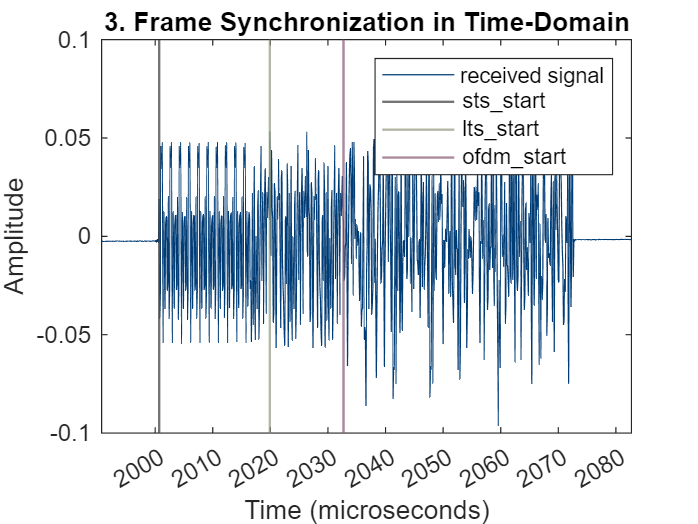

sts_start = lts_start - 32 - 160;

% plot the location of estimated starts
figure;
time_vector = (sec_beg:sec_end);
plot(time_vector, real(buffer(sec_beg:sec_end)), 'Color', '#003C76');
hold on
xline(sts_start, 'Color', '#393939','LineWidth', 1);
xline(lts_start, 'Color', '#939880','LineWidth', 1);
xline(ofdm_start, 'Color', '#875B75','LineWidth', 1);

hold off
xlim([sec_beg sec_end])
xt = xticks;
xticklabels(xt * ts*1e6);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('3. Frame Synchronization in Time-Domain');
legend('received signal','sts\_start', 'lts\_start', 'ofdm\_start')

**(4)** Based on the result, what index marks the beginning of the first long training symbols?

**Answer: **The beginning of the first LTS is at index = 20199 (stored in variable "lts_start").

**(5) **Transform the first long training symbol into the frequency domain and perform channel estimation. Plot the magnitude and phase of the channel across the subcarriers, from subcarrier index -26 to 26 (zero-subcarrier in the center).

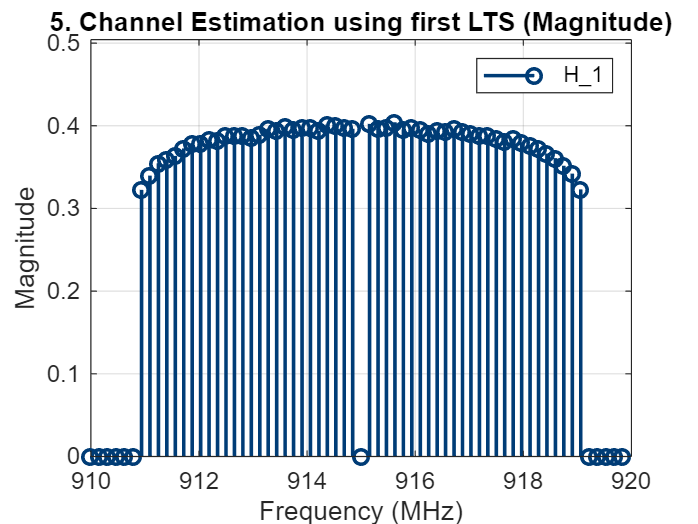

function H_est = channel_est_LTS(buffer_trimmed, lts_start)
    LTS_val =  [1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,1,1,-1,-1,1,1,-1,1,-1,1,1,1,1,0,1, ...
        -1, -1, 1, 1, -1, 1,-1, 1,-1,-1,-1,-1,-1, 1, 1,-1,-1, 1,-1,1,-1,1,1,1,1];

    LTS_val_new = [zeros(1, 6),LTS_val, zeros(1, 5)];

    lts_1 = buffer_trimmed(lts_start : lts_start+64-1);

    LTS_1_RX = fftshift(fft(lts_1));

    H1 = zeros(64, 1);

    est_idx = [(-26+33: 26+33)]; % -26 to 26 except '0'
    H1(est_idx) = LTS_1_RX(est_idx).*LTS_val.';
    H_est = H1;
end

close all;
H_est = channel_est_LTS(buffer(sec_beg:sec_end), lts_start-sec_beg+1);
H1 = H_est;

freq_vector = 915*1e6 + (-64/2:64/2-1) * (fs/64); % Frequency in MHz

% plot magnitude
figure(1);
s1 = stem(freq_vector/1e6, abs(H1), 'Color', '#003C76', 'LineWidth', 1.5);hold on;

xlabel('Frequency (MHz)');
ylabel('Magnitude');

axis([910 920 0 max(abs(H1))+0.1])
legend([s1(1)],'H\_1');
title('5. Channel Estimation using first LTS (Magnitude)');
grid on;
hold off;

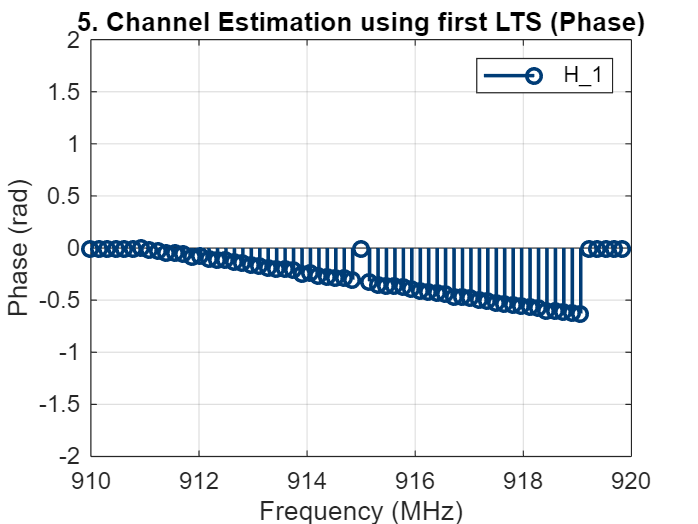


% plot phase
figure(2);
s1 = stem(freq_vector/1e6, angle(H1), 'Color', '#003C76', 'LineWidth', 1.5);

xlabel('Frequency (MHz)');
ylabel('Phase (rad)');
axis([910 920 -2 2])
legend([s1(1)],'H\_1');
title('5. Channel Estimation using first LTS (Phase)');
grid on;
hold off;

**(6) **Similar to (5), perform channel estimation using the second long training symbol. Plot the magnitude and phase of the channel across the subcarriers, from subcarrier index -26 to 26 (zero-subcarrier in the center). For comparison, plot the results using the first long training symbol on the same figure with a clear legend.

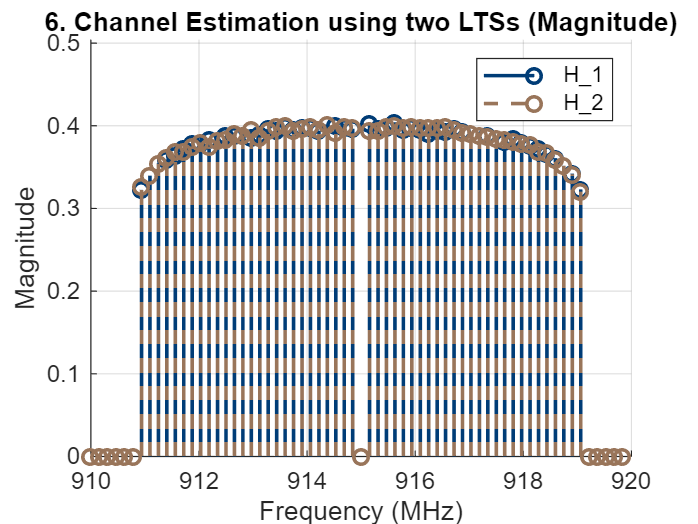

close all;
H_est = channel_est_LTS(buffer(sec_beg:sec_end), lts_start-sec_beg + 1 +64);
H2 = H_est;

% plot magnitude
figure(1); hold on;
s1 = stem(freq_vector/1e6, abs(H1), 'Color', '#003C76', 'LineWidth', 1.5);hold on;
s2 = stem(freq_vector/1e6, abs(H2), '--', 'Color', '#99755A', 'LineWidth', 1.5);
xlabel('Frequency (MHz)');
ylabel('Magnitude');
axis([910 920 0 max(abs(H1))+0.1])

legend([s1(1), s2(1)],'H\_1', 'H\_2');
title('6. Channel Estimation using two LTSs (Magnitude)');
grid on;
hold off;

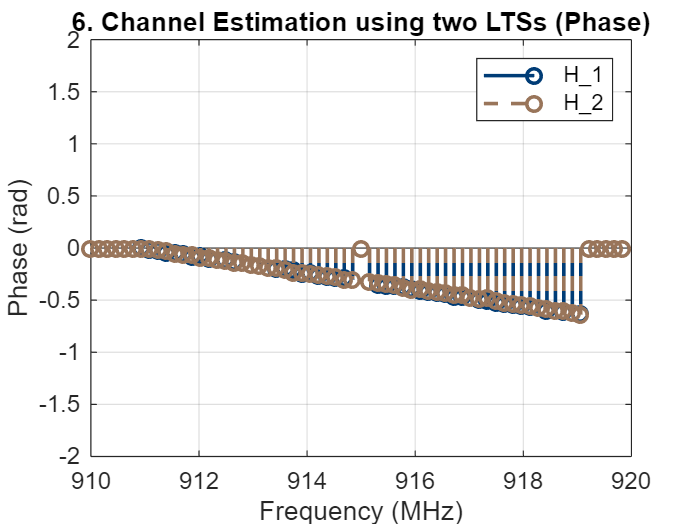


% plot phase
figure(2);
s1 = stem(freq_vector/1e6, angle(H1), 'Color', '#003C76', 'LineWidth', 1.5);hold on;
s2 = stem(freq_vector/1e6, angle(H2), '--', 'Color', '#99755A', 'LineWidth', 1.5);
xlabel('Frequency (MHz)');
ylabel('Phase (rad)');
axis([910 920 -2 2])
legend([s1(1), s2(1)],'H\_1', 'H\_2');
title('6. Channel Estimation using two LTSs (Phase)');
grid on;
hold off;

**(7)** What frequencies do subcarriers -26, 0, and 26 correspond in this USRP transmission?

Ans: As defined in USRP_init.m, the center frequency of USRP is 915MHz = 0.915GHz = $f_0$.

Sub carrier spacing $\Delta f=\frac{f_s }{64}=156\ldotp 25\;\textrm{kHz}$.

$f_{-26} =f_0 -\Delta f\cdot 26=910\ldotp 9375\;\textrm{MHz}$.

$f_{26} =f_0 +\Delta f\cdot 26=919\ldotp 0625\;\mathrm{MHz}$.

**(8)** Find the samples corresponding to the OFDM symbols. Before equalization, plot the received constellation for data tones. What do you observe?

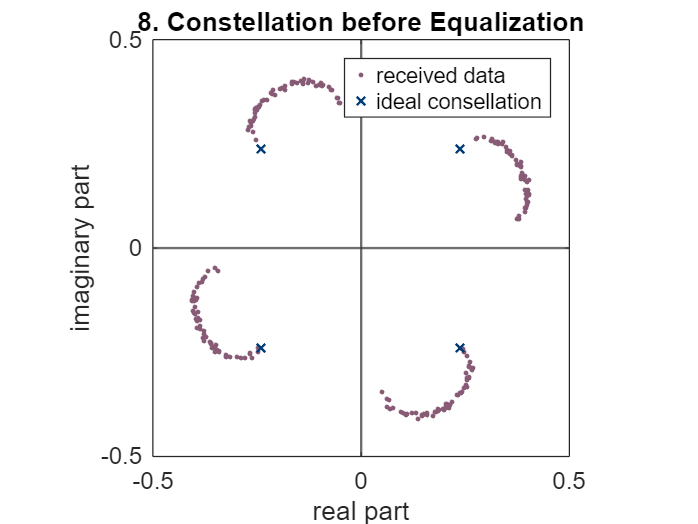

ofdm_rx_CP = reshape(...
    buffer(ofdm_start:(ofdm_start+(N_FFT+N_CP)*5-1)),...
    [], 5);

ofdm_rx = zeros(N_FFT, 5);
ofdm_rx_sym = zeros(N_FFT, 5);

for ii = 1:5
    ofdm_rx(:,ii) = ofdm_removeCP(ofdm_rx_CP(:, ii));
    ofdm_rx_sym(:, ii) = fftshift(fft(ofdm_rx(:, ii)));
end


% ideal symbols
M = 4;  % 4-QAM
ideal_symbols = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);
Ii = real(ideal_symbols * mean(mean(abs(ofdm_rx_sym))));
Qi = imag(ideal_symbols * mean(mean(abs(ofdm_rx_sym))));

figure;
plot(reshape(ofdm_rx_sym(data_idx, :), 1, []), 'o','Color', '#875B75', 'MarkerFaceColor', '#875B75', 'MarkerSize', 1.5); hold on;

xlim([-0.5 0.5])
ylim([-0.5 0.5])
xlabel("real part");
ylabel("imaginary part");
% plot ideal symbol
plot(Ii, Qi, 'x', 'Color', '#003C76', 'MarkerSize', 5, 'LineWidth', 1);
xline(0, 'Color', '#393939','LineWidth', 1);
yline(0, 'Color', '#393939','LineWidth', 1);
axis square;
grid on;
legend('received data', 'ideal consellation')
title("8. Constellation before Equalization")

**Observation:** The data tones are uniformly shifted by some phase, and the amplitude is also varied and is highly correlated to the phase shifted. The shifting pattern of tones around each ideal constellation position are identical.

Comparing this figure to the result of channel estimation, we can assume that the tones close to the ideal position has the smallest frequency. The more the frequency is, the more phase shift it have, and the amplitude of tones in the middle is larger than the tones at the sides.

**(9) **We skip the carrier frequency offset estimation and correction since we use the same USRP for transmission and reception in this experiment. Thus, without correcting carrier frequency offset, **equalize the OFDM symbols** using the estimated channel in (5) and (6) in the frequency domain. Plot the equalized received constellation for the data tones. Also, plot the transmitted constellation in the same figure for comparison. What do you observe?

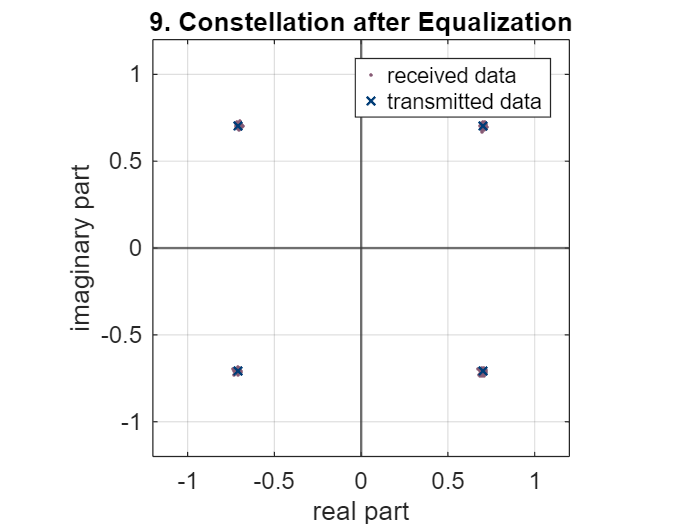

% equalized signal initialization
ofdm_eq = zeros(N_FFT, 5);
ofdm_eq_sym = zeros(N_FFT, 5);

% transmitted signal initialization
ofdm_tx_CP = reshape(...
    sig_5(L_sig_5_head+1:end),...
    [], 5);
ofdm_tx_sym = zeros(N_FFT, 5);

% Estimated Channel
H_est = (H1 + H2)/2;
idx_est = find(H_est>eps); % indices that H_est are not zero

% Equalization
for ii = 1:5
    ofdm_eq_sym(idx_est, ii) = ofdm_rx_sym(idx_est, ii)*10./H_est(idx_est);
    ofdm_tx_sym(:, ii) = fftshift(fft(ofdm_removeCP(ofdm_tx_CP(:, ii))));
end

% Uniform
ofdm_eq_data = reshape(ofdm_eq_sym(data_idx, :), 1, []);
ofdm_eq_data = ofdm_eq_data/mean(abs(ofdm_eq_data));
ofdm_tx_data = reshape(ofdm_tx_sym(data_idx, :), 1, []);
ofdm_tx_data = ofdm_tx_data/mean(abs(ofdm_tx_data));

% Plot 
% ideal symbols
M = 4;  % 16-QAM
ideal_symbols = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);
Ii = real(ideal_symbols);
Qi = imag(ideal_symbols);

figure;
plot(ofdm_eq_data, 'o','Color', '#875B75', 'MarkerFaceColor', '#875B75', 'MarkerSize', 1); hold on;

xlim([-1.2 1.2])
ylim([-1.2 1.2])
xlabel("real part");
ylabel("imaginary part");
% plot ideal symbol
plot(Ii, Qi, 'x', 'Color', '#003C76', 'MarkerSize', 5, 'LineWidth', 1);
xline(0, 'Color', '#393939','LineWidth', 1);
yline(0, 'Color', '#393939','LineWidth', 1);
axis square;
grid on;
legend('received data', 'transmitted data')
title("9. Constellation after Equalization")

**Observation:** The data tones are all recoverd to the ideal constellation position with small error.

**(10)** Use the samples of the 5 OFDM symbols for signal strength calculation, and use the padded zeros for noise calculation. What is the SNR of this received frame in dB?

function SNR = calc_SNR(buffer, idx_ofdm, idx_noise, idx_data)
    buffer_data_CP = reshape(buffer(idx_ofdm), 80 ,[]);
    P_sig = 0;
    for ii = 1:width(buffer_data_CP)
        buffer_data = ofdm_removeCP(buffer_data_CP(:, ii));
        buffer_data_fft = fftshift(fft(buffer_data));
        P_sig = P_sig + mean(abs(buffer_data_fft(idx_data).^2));
    end
    P_sig = P_sig / width(buffer_data_CP);
    P_noise = mean(abs(buffer(idx_noise)).^2);
    SNR = P_sig/P_noise;
end


idx_ofdm = ofdm_start:(ofdm_start + (N_OFDM)*5 - 1);
idx_zero_l_end = ofdm_start - 320 - 1;
idx_zero_l_beg = idx_zero_l_end - 100 + 1;
idx_zero_r_beg = ofdm_start + (N_OFDM)*5;
idx_zero_r_end = idx_zero_r_beg + 100 - 1;
idx_noise = [idx_zero_l_beg:idx_zero_l_end,...
        idx_zero_r_beg:idx_zero_r_end];
SNR = calc_SNR(buffer, idx_ofdm, idx_noise, data_idx);
SNR_dB = 10*log10(SNR)

SNR_dB = 39.9908

**Answer:** $\mathrm{SNR}\approx 40\;\mathrm{dB}$

**(11)** Instead of transmitting only 5 OFDM symbols in each frame, increase to 100 OFDM symbols per frame. Repeat frame transmission 100 times and calculate BER.

time_11_start = tic;
addpath("./test_code/")

iter_time   = 20;                                   % numbers of frame
num_symbol  = 100;                                  % number of symbols in a frame
L_sig_100   = L_sig_5_head + num_symbol * (N_OFDM);

% Frame generation
function [sym_golden, sig_100] = big_frame_generation( ...
    num_symbol, L_sig_5_head, N_OFDM, STS, LTS, amp, mod_size)
    global data_idx;
    L_sig_100  = L_sig_5_head + num_symbol * (N_OFDM);
    sym_golden = zeros(48*num_symbol, 1); 
    sig_100    = zeros(L_sig_100, 1);
    sig_100(1:length(STS)) = STS;
    sig_100(length(STS)+1:length(STS)+length(LTS))= LTS;
    for ii = 0 : num_symbol-1
        X_golden    = ofdm_generate(mod_size);      %f
        sig_a       = ifft(ifftshift(X_golden));    %t
        x_cp        = ofdm_addCP(sig_a);            %t
        sym_golden(48*ii+1 : 48*(ii+1)) = X_golden(data_idx);
        sig_100(L_sig_5_head + ii*(N_OFDM)+1 : ...
                L_sig_5_head + (ii+1)*(N_OFDM)) = x_cp;
    end
    sig_100(L_sig_5_head+1:end) = amp * sig_100(L_sig_5_head+1:end) ...
                              /mean(abs(sig_100(L_sig_5_head+1:end)));
end

% Transmission
addpath("./test_code/")
function buffer_big = multi_frame_transmission(padded_sig_100, iter_time)
    l_big = length(padded_sig_100);
    [radio_Tx,radio_Rx] = USRP_init(l_big);
    buffer_big = zeros((iter_time+1)*l_big, 1);
    for ii = 1:iter_time
        tunderrun = radio_Tx(padded_sig_100);
        [rcvdSignal, ~, toverflow] = step(radio_Rx);
        buffer_big((1+(ii-1)*l_big):(ii*l_big)) = rcvdSignal;
    end
    [rcvdSignal, ~, toverflow] = step(radio_Rx);
    buffer_big((1+iter_time*l_big):((iter_time+1)*l_big)) = rcvdSignal;
    release(radio_Tx);
    release(radio_Rx);
end

% Get BER
iter_time_p = iter_time - 1;

function [sec_index, lts_start, ofdm_start, sym_emp, SNR] = get_BER(buffer_big, ...
    iter_time_p, num_symbol, single_STS, single_LTS, L_sig_100, amp)
    global N_FFT;
    global N_CP;
    global data_idx;
    global zero_idx;
    sym_emp     = zeros(48*num_symbol, iter_time_p);    
    sec_index   = zeros(2, iter_time_p);
    lts_start   = zeros(1, iter_time_p);
    ofdm_start  = zeros(1, iter_time_p);
    buffer_big_backup = buffer_big;
    SNR = zeros(1, iter_time_p);
    for ii = 1:iter_time_p
        temp            = abs(conv(buffer_big_backup, single_STS, "same"));
        potential       = find(temp>0.01);
        start           = potential(1) - 100;
        sec_index(1,ii) = start;
        sec_index(2,ii) = start+L_sig_100+200;                                            % sync-1
        buffer_big_backup(sec_index(1,ii):sec_index(2,ii)) = 0;
    end
    for ii = 1:iter_time_p
        buffer_big(sec_index(2,ii)-100-num_symbol*(N_CP+N_FFT) : sec_index(2,ii)-100) ...
        = buffer_big(sec_index(2,ii)-100-num_symbol*(N_CP+N_FFT) : sec_index(2,ii)-100) / amp;
    end
    for ii = 1:iter_time_p
        [lts_start(ii), ofdm_start(ii)] = LTS_CONV(buffer_big( ...
            sec_index(1,ii):sec_index(2,ii)), sec_index(1,ii), single_LTS);               % sync-2
        SNR(:, ii) = amp * ...
            mean( abs( buffer_big(ofdm_start(ii): ...
                                  ofdm_start(ii)+num_symbol*(N_FFT+N_CP)-1)).^2 )/ ...
            mean( abs([buffer_big(sec_index(1,ii) : lts_start(ii)-176);...
            buffer_big(ofdm_start(ii)+num_symbol*(N_FFT+N_CP) : sec_index(2,ii))]).^2 );  % SNR
        H_est                   = channel_est_LTS(buffer_big( ...
            sec_index(1,ii):sec_index(2,ii)), lts_start(ii)-sec_index(1,ii)+1);           % CE
        sym_in_buffer           = reshape(buffer_big(ofdm_start(ii): ...
            (ofdm_start(ii)+(N_FFT+N_CP)*num_symbol-1)), [], num_symbol);
        sym_in_buffer           = sym_in_buffer(N_CP+1 : end, :);                         % rm CP
        sym_in_buffer_freq      = fftshift(fft(sym_in_buffer, [], 1), 1);                 % FFT
        sym_emp_single_frame    = sym_in_buffer_freq(data_idx, :) ./ H_est(data_idx, :);  % Equ
        sym_emp(:, ii)          = reshape(sym_emp_single_frame, [], 1);
    end
end

mod_size_11 = 4;
error_bits = zeros(iter_time/10, 1);

[sym_golden, sig_100] = big_frame_generation( ...
    num_symbol, L_sig_5_head, N_OFDM, STS, LTS, 5, mod_size_11); % mod amp here
padded_sig_100 = send_amp * [zeros(100, 1); sig_100; zeros(100, 1)];
bit_golden = qamdemod(sym_golden, 4, OutputType="bit");
bit_golden = repmat(bit_golden, [1,10]);    

for ind = 1:iter_time/10
    buffer_big = multi_frame_transmission(padded_sig_100, 11);
    buffer_big2 = buffer_big;
    [sec_index, lts_start, ofdm_start, sym_emp, SNR] = get_BER(buffer_big, ...
        10, num_symbol, single_STS, single_LTS, L_sig_100, 5); % mod amp here
    bit_emp         = qamdemod(sym_emp, mod_size_11, OutputType="bit");
    error_bits(ind) = sum(xor(bit_emp, bit_golden), "all");
end
SER_final   = mean(SNR);
BER_final   = sum(error_bits)/(numel(bit_golden)*10);
time_11     = toc(time_11_start);
fprintf("(11)");

(11)

fprintf("BER: %f", BER_final);

BER: 0.010111

% close all;
% test code
% ii=1;
% range = sec_index(1,ii):sec_index(1,ii)+320+100;
% plot(range, real(buffer_big(range)))
% hold on;
% stem(lts_start(ii), 0.2)
% hold on;
% stem(ofdm_start(ii), 0.2)
% hold on
% plot(range, temp(range-sec_index(1,ii)+1))
% legend('1','2','3')

**(12)** Following (11), how many bits are transmitted to obtain one BER value? As a side note, many wireless experiments aim for a BER level in the order of 10^9. If we want to reach a BER precision in the order of 10^9, how many times do you need to repeat the frame transmission? How long does it take to perform the experiment in (11)? How much time is expected if we were to reach a BER precision in the order of 10^9?

target = 1e9;
bits_per_frame = 2*48*100;
fprintf("(12)");

(12)

fprintf("Bits to transmit: %e", ceil(100*bits_per_frame));

Bits to transmit: 9.600000e+05

fprintf("Times to repeat the frame transmission: %d", ceil(target/bits_per_frame));

Times to repeat the frame transmission: 104167

fprintf("Time to perform the experiment in (11): %f (s)", time_11);

Time to perform the experiment in (11): 60.556296 (s)

fprintf("The expected time to perform the experiment: %f (hr)", ...
    ceil(target/bits_per_frame) * time_11 / (100*3600));

The expected time to perform the experiment: 17.522132 (hr)

**(13) **Vary the transmit power digitally and calculate BER in each power setting as in (11). Plot BER vs SNR in dB. Please explore a range of power so that you observe BER reduction with increasing transmit power. Also, increase the transmit power until clipping happens, which may result in additional errors despite a large received signal strength. Please briefly describe your figure. As a side note, a trick to vary the transmit power is to vary only the amplitude of the OFDM symbols, not the STS and LTS. As a result, you will be able to detect the beginning of the frame regardless of the power of the OFDM symbols. However, when using this method, you need to remember the amplification factor between LTS and the OFDM symbols and scale the estimated channel accordingly.

iter_time = 10;
mod_size_13 = 4;
% amp_arr     = [1e-4, 1e-3, 2e-3, 5e-3, 5, 10];
% amp_arr     = 1e-3;
amp_arr        = 1; 
SNR_big_13     = zeros(1, length(amp_arr));
BER_big_13     = zeros(1, length(amp_arr));
for ii = 1:length(amp_arr)
    [sym_golden, sig_100] = big_frame_generation( ...
        num_symbol, L_sig_5_head, N_OFDM, STS, LTS, amp_arr(ii), mod_size_13); % mod amp here
    padded_sig_100 = send_amp * [zeros(100, 1); sig_100; zeros(100, 1)];
    bit_golden = qamdemod(sym_golden, mod_size_13, OutputType="bit");
    bit_golden = repmat(bit_golden, [1,10]);
    error_bits = zeros(iter_time/10, 1);
    for ind = 1:iter_time/10
        buffer_big = multi_frame_transmission(padded_sig_100, 11);
        [sec_index, lts_start, ofdm_start, sym_emp, SNR_big_13(ii)] = get_BER(buffer_big, ...
            10, num_symbol, single_STS, single_LTS, L_sig_100, amp_arr(ii)); % mod amp here
        bit_emp         = qamdemod(sym_emp, mod_size_13, OutputType="bit");
        error_bits(ind) = sum(xor(bit_emp, bit_golden), "all");
    end
    BER_big_13(ii)   = sum(error_bits)/(numel(bit_golden)*iter_time/10);
end

Unable to perform assignment because the left and right sides have a different number of elements.


SNR_big_13 = 10 * log(SNR_big_13);
close all;
semilogy(SNR_big_13, BER_big_13)
title('13. BER vs SNR in dB in 4-QAM scheme');
xlabel('SNR (db)')
ylabel('BER (in log scale)')
ylim(0.2*min(BER_big_13), 5*max(BER_big_13))

**(14)** Repeat (13) for 16-QAM. Plot BER vs SNR in dB.

mod_size_14 = 16;
% amp_arr     = [1e-4, 1e-3, 2e-3, 5e-3, 5, 10];
% amp_arr     = 1e-3;
amp_arr        = [5, 10];
SNR_big_14     = zeros(1, length(amp_arr));
BER_big_14     = zeros(1, length(amp_arr));
for ii = 1:length(amp_arr)
    [sym_golden, sig_100] = big_frame_generation( ...
        num_symbol, L_sig_5_head, N_OFDM, STS, LTS, amp_arr(ii), mod_size_14); % mod amp here
    padded_sig_100 = send_amp * [zeros(100, 1); sig_100; zeros(100, 1)];
    bit_golden = qamdemod(sym_golden, mod_size_14, OutputType="bit");
    bit_golden = repmat(bit_golden, [1,10]);
    error_bits = zeros(iter_time/10, 1);
    for ind = 1:iter_time/10
        buffer_big = multi_frame_transmission(padded_sig_100, 11);
        [sec_index, lts_start, ofdm_start, sym_emp, SNR_big_14(ii)] = get_BER(buffer_big, ...
            10, num_symbol, single_STS, single_LTS, L_sig_100, amp_arr(ii)); % mod amp here
        bit_emp         = qamdemod(sym_emp, mod_size_14, OutputType="bit");
        error_bits(ind) = sum(xor(bit_emp, bit_golden), "all");
    end
    BER_big_14(ii)   = sum(error_bits)/(numel(bit_golden)*iter_time/10);
end

SNR_big_14 = 10 * log(SNR_big_14);
close all;
semilogy(SNR_big_14, BER_big_14)
title('14. BER vs SNR in dB in 16-QAM scheme');
xlabel('SNR (db)')
ylabel('BER (in log scale)')
ylim(0.2*min(BER_big_14), 5*max(BER_big_14))

**(15)** Compare the results for 4-QAM in (13) with the results for 16-QAM in (14). What do you observe?

close all;
semilogy(SNR_big_13, BER_big_13)
hold on;
semilogy(SNR_big_14, BER_big_14)
title('14. Comparison of BER in 4-QAM and 16-QAM scheme');
xlabel('SNR (db)')
ylabel('BER (in log scale)')
ylim(0.2*min([BER_big_13, BER_big_14]), 5*max([BER_big_13, BER_big_14]))
legend(['4-QAM', '16-QAM'])

**[Part 2] CFO Estimation and correction**

**(1)** Add a 5 ppm artificial CFO to the transmitted frame (with 100 OFDM symbols). Transmit and receive the frame using the same USRP. Estimate the channel using the two long training symbols. Plot the magnitude and phase of the estimated channel for both estimates across the subcarriers, from subcarrier index -26 to 26 (zero-subcarrier in the center). What do you observe?

num_of_symbol = 100; 

function tx_sig_CFO = TX_CFO(sig, L)
    global ts;
    global fc;
    global fs;
    PPM = 5;
    delta_f= fc*PPM/1e6;
    
    t = (0:L-1) * ts;
    idx = exp(1j*2*pi* delta_f .*t);
    tx_sig_CFO = sig .* idx(:);
end

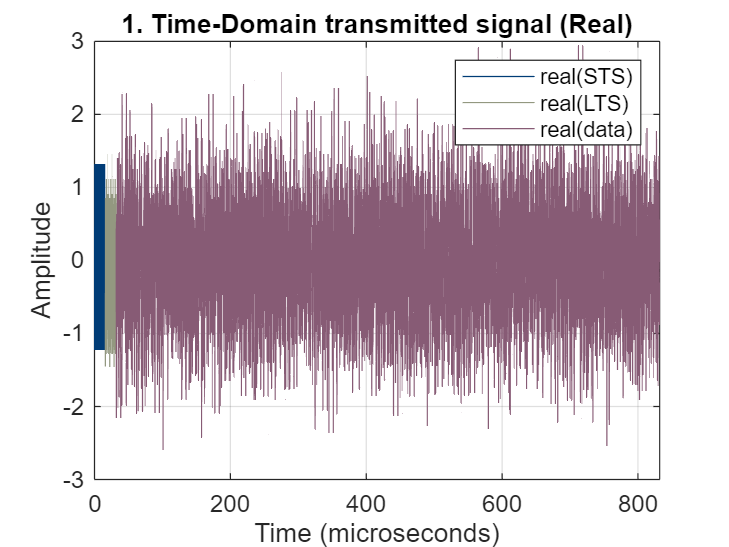

if REGEN_SIG_FLAG_100_single == 0
    load('single_100.mat');

elseif REGEN_SIG_FLAG_100_single == 1
    %% (1) Compute and plot magnitude spectrum
    [STS, single_STS] = STS_generate();
    [LTS, single_LTS] = LTS_generate();
    single_LTS = LTS(end-64+1:end);
    % pre-save data_bits
    data_tx = zeros(num_of_symbol*48, 1);
    
    % generate 100 OFDM Symbols
    for i = 0:num_of_symbol-1
        X = ofdm_generate(4); % generate single OFDM symbol
        X_shifted = ofdm_shift(X); 
        sig_a = ifft(ifftshift(X_shifted));
        x_cp = ofdm_addCP(sig_a);
        data_tx(48*i+1 : 48*(i+1)) = X(data_idx);
        sig_100(L_sig_5_head + i*(N_OFDM)+1 : L_sig_5_head+(i+1)*(N_OFDM)) = x_cp;
    end
    sig_100(L_sig_5_head+1:end) = sig_100(L_sig_5_head+1:end)/mean(abs(sig_100(L_sig_5_head+1:end)));
    sig_100(1:length(STS)) = STS;
    sig_100(length(STS)+1:length(STS)+length(LTS) )= LTS;
    bits_tx = qamdemod(data_tx, 4, 'gray', OutputType='bit', UnitAveragePower=true);

    sig_100 = sig_100(:);
end
figure;
plot(real(sig_100))

time_vector = (0:L_sig_100-1) * ts * 1e6; % Time in microseconds

close all;
figure;
p1 = plot(time_vector(1:length(STS)), real(sig_100(1:length(STS))), 'Color', '#003C76', 'LineWidth', 0.5);
hold on;
p2 = plot(time_vector(length(STS)+1:L_sig_5_head), real(sig_100(length(STS)+1:L_sig_5_head) ),'Color', '#939880', 'LineWidth', 0.5);
p3 = plot(time_vector(L_sig_5_head+1:end), real(sig_100(L_sig_5_head+1:end)),'Color', '#875B75', 'LineWidth', 0.5);
xlabel('Time (microseconds)'); ylabel('Amplitude');
axis([0 832 -3 3])
title('1. Time-Domain transmitted signal (Real)');
legend([p1(1), p2(1), p3(1)],'real(STS)', 'real(LTS)','real(data)');
grid on;
hold off;

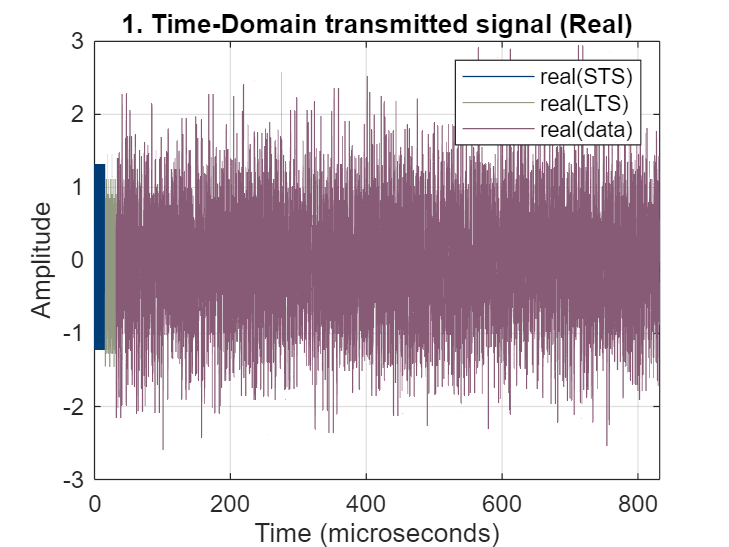

if REGEN_SIG_FLAG_100_single == 0
    load('single_100.mat');
elseif REGEN_SIG_FLAG_100_single == 1

    addpath("./test_code/");
    tx_sig_100_CFO = TX_CFO(sig_100, length(sig_100));
    padded_sig_100 = send_amp*[zeros(100, 1); tx_sig_100_CFO; zeros(100, 1)];
    
    l = length(padded_sig_100);
    [radio_Tx,radio_Rx] = USRP_init(l);
    buffer_CFO = zeros(30*l, 1);
    
    % Transmit the frame we generate
    
    % Transmit 15 zero frames 
    % (Otherwise there will be no output.) 
    % (I not yet know why this bug happens.)
    for ii = 1:20
        if ii == 8
            tunderrun = radio_Tx(padded_sig_100);
        else
            tunderrun = radio_Tx(complex(zeros(l, 1)));
        end
        % step(radio_Rx);
        [rcvdSignal, ~, toverflow] = step(radio_Rx);
        buffer_CFO((1+(ii-1)*l):(ii*l)) = rcvdSignal;
    end
    
    % Keep reception for 15 frames 
    for ii = 21 : 30
        [rcvdSignal, ~, toverflow] = step(radio_Rx);
        buffer_CFO((1+(ii-1)*l):(ii*l)) = rcvdSignal;
    end 
    
    % To save new data, uncomment this line. 
    % Otherwise, keep it commented so that rx_sig.mat won't be modified.
    % save rx_sig.mat buffer
    
    release(radio_Tx)
    release(radio_Rx)
    % buffer_CFO = multi_frame_transmission(tx_sig_100_CFO, 2);
end
%--------------------

buffer = buffer_CFO;


%Trim and get sec_beg and sec_end
plot_len = 8500; % 要取多長平均
sec_blank = 100;  %兩邊留多長
[sec_beg, sec_end] = trim_buffer(buffer, plot_len, sec_blank);

hold off;


[lts_start, ofdm_start] = LTS_CONV(buffer(sec_beg:sec_end), sec_beg,  single_LTS)

lts_start = 61904

ofdm_start = 62032

sts_start = lts_start - 32 - 160;

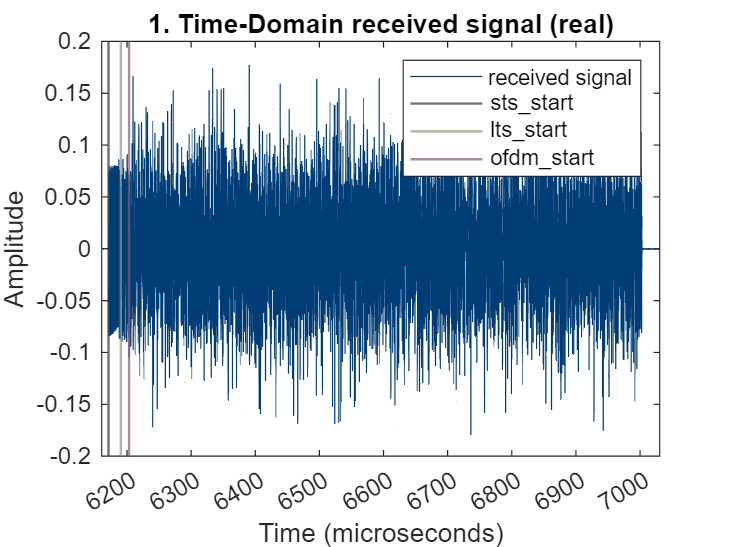

% plot the location of estimated starts
figure;
time_vector = (sec_beg:sec_end);
plot(time_vector, real(buffer(sec_beg:sec_end)), 'Color', '#003C76');
hold on
xline(sts_start, 'Color', '#393939','LineWidth', 1);
xline(lts_start, 'Color', '#939880','LineWidth', 1);
xline(ofdm_start, 'Color', '#875B75','LineWidth', 1);

hold off
xlim([sec_beg sec_end])
xt = xticks;
xticklabels(xt * ts*1e6);
xlabel('Time (microseconds)');
ylabel('Amplitude');
title('1. Time-Domain received signal (real)');
legend('received signal','sts\_start', 'lts\_start', 'ofdm\_start')


H1 = channel_est_LTS(buffer(sec_beg:sec_end), lts_start-sec_beg+1);
H2 = channel_est_LTS(buffer(sec_beg:sec_end), lts_start-sec_beg+1+64);
H_est = (H1+H2)/2;


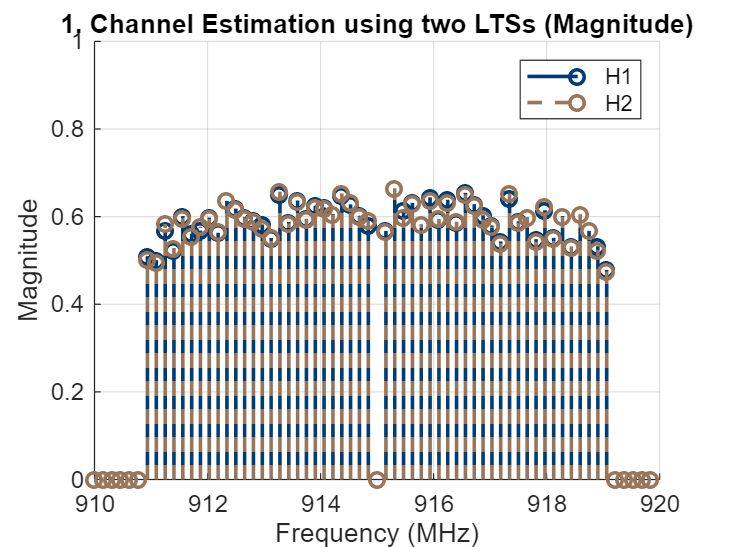


% plot magnitude
freq_vector = 915*1e6 + (-64/2:64/2-1) * (fs/64);
close all;
figure(1); hold on;
s1 = stem(freq_vector/1e6, abs(H1), 'Color', '#003C76', 'LineWidth', 1.5);hold on;
s2 = stem(freq_vector/1e6, abs(H2), '--', 'Color', '#99755A', 'LineWidth', 1.5);
xlabel('Frequency (MHz)');
ylabel('Magnitude');
axis([910 920 0 1]);
legend([s1(1), s2(1)],'H1', 'H2');
title('1. Channel Estimation using two LTSs (Magnitude)');
grid on;
hold off;

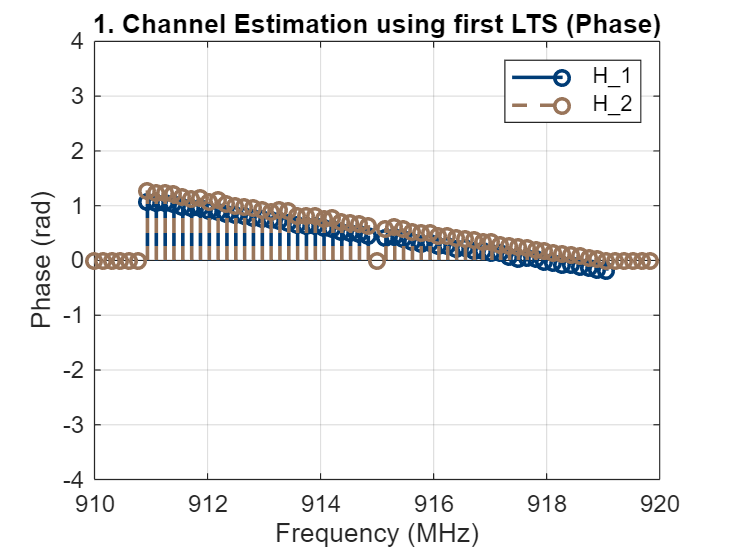


% plot phase
figure(2);
s1 = stem(freq_vector/1e6, angle(H1), 'Color', '#003C76', 'LineWidth', 1.5);hold on;
s2 = stem(freq_vector/1e6, angle(H2), '--', 'Color', '#99755A', 'LineWidth', 1.5);
xlabel('Frequency (MHz)');
ylabel('Phase (rad)');
axis([910 920 -4 4])
legend([s1(1), s2(1)],'H\_1', 'H\_2');
title('1. Channel Estimation using first LTS (Phase)');
grid on;
hold off;

**Obeservation:**

Magnitude of channels H1 and H2 are basically the same. However, the phase of H1 and H2 has a transition relation. 

**(2)** Use the estimated channel in (1) for equalization. Plot the received constellation with equalization but without CFO correction (as in Part 1). What do you observe?

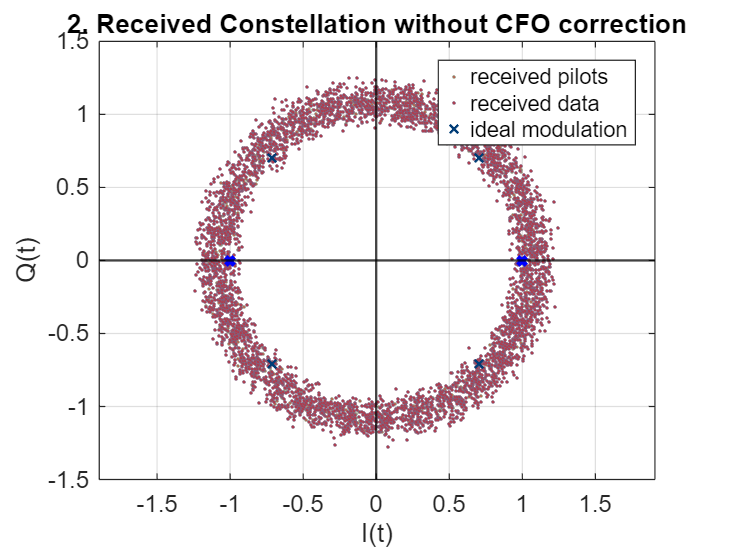

function  [Pilot, Data] = Equalize(Symbol, H) % freq domain
    global data_idx;
    global pilot_idx;
    Y = Symbol;

    Data = zeros(48, 1);
    Pilot = zeros(4, 1);

    data_nonzero_idx = data_idx(H(data_idx) ~= 0);

    Data = Y(data_idx)./H(data_idx);
    Pilot = Y(pilot_idx)./H(pilot_idx);
end

Data_rx = zeros(48*num_of_symbol, 1);
Pilot_rx = zeros(4*num_of_symbol, 1);

P_OFDM = mean(abs (buffer(ofdm_start:ofdm_start + 80*num_of_symbol-1) ) );
for ii = 0:num_of_symbol-1 %!!!!!P_OFDM to be determined
    sig_c = ofdm_removeCP(buffer(ofdm_start + ii*(N_FFT+N_CP) : ofdm_start-1 + (ii+1)*(N_FFT+N_CP)));
    X_rx = fftshift(fft(sig_c));
    [Pilot, Data] = Equalize(X_rx, H_est); % H_est = (H1+H2)/2;
    Data_rx(48*ii+1 : 48*(ii+1)) = Data;
    Pilot_rx(4*ii+1 : 4*(ii+1)) = Pilot;
end


I_data = real(Data_rx);
Q_data = imag(Data_rx);
I_pilot = real(Pilot_rx);
Q_pilot = imag(Pilot_rx);

% ideal symbols
M = 4;  % 16-QAM
ideal_symbols = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);
Ii = real(ideal_symbols);
Qi = imag(ideal_symbols);

% plot data and pilot
figure;
plot(I_pilot, Q_pilot, 'o','Color', '#939880', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 
hold on;
plot(I_data, Q_data, 'o', 'Color', '#875B75', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 

% plot ideal symbol
plot(Ii, Qi, 'x', 'Color', '#003C76', 'MarkerSize', 5, 'LineWidth', 1);
I_bpsk = [1, -1];
Q_bpsk = [0, 0];
plot(I_bpsk, Q_bpsk, 'bx', 'MarkerSize', 5, 'LineWidth', 2); 
 

axis([-1.5 1.5 -1.5 1.5]);
xlabel('I(t)');
ylabel('Q(t)');

xline(0, 'k', 'LineWidth', 1); % Real axis (vertical)
yline(0, 'k', 'LineWidth', 1); % Imaginary axis (horizontal)
legend({'received pilots', 'received data', 'ideal modulation'}, 'Location', 'northeast');
title('2. Received Constellation without CFO correction');

axis equal;
grid on;
hold off;

**Observation:**

Without CFO correction, the constellation looks like a ring instead of concentrating around ideal points. The average energy remains on unit circle. I will intuitively guess that there is still gaussian distribution on every cut of the ring.  

**(3)** Estimate CFO from the received frame using two consecutive short training symbols. What is the estimated CFO? Next, estimate the CFO using two non-consecutive short training symbols, in particular, the 8th and the 10th short training symbols. What is the estimated CFO using non- consecutive short training symbols?

% consecutive
sts_start_8th = sts_start + 16*(8-1);
sts_8th = buffer(sts_start_8th : sts_start_8th+16-1);
sts_start_9th = sts_start + 16*(9-1);
sts_9th = buffer(sts_start_9th : sts_start_9th+16-1);

phase_diff = angle(sum(sts_9th .* conj(sts_8th)));
cfo_hz_sts = phase_diff / (2*pi*16*ts);  % 32 is time diff between 8th and 10th

cfo_ppm_sts = cfo_hz_sts / fc * 1e6;

fprintf("CFO estimated by consecutive 8th and 9th STS(PPM) = %.2f", cfo_ppm_sts);

CFO estimated by consecutive 8th and 9th STS(PPM) = 5.22


% non - consecutive
sts_start_8th = sts_start + 16*(8-1);
sts_8th = buffer(sts_start_8th : sts_start_8th+16-1);
sts_start_10th = sts_start + 16*(10-1);
sts_10th = buffer(sts_start_10th : sts_start_10th+16-1);

phase_diff = angle(sum(sts_10th .* conj(sts_8th)));
cfo_hz_sts = phase_diff / (2*pi*32*ts);  % 32 is time diff between 8th and 10th

cfo_ppm_sts = cfo_hz_sts / fc * 1e6;

fprintf("CFO estimated by non-consecutive 8th and 10th STS(PPM) = %.2f", cfo_ppm_sts);

CFO estimated by non-consecutive 8th and 10th STS(PPM) = 6.00

**Answer: **(Using our data set - "single_100.mat")

`CFO estimated by consecutive 8th and 9th STS(PPM) = 5.22`

`CFO estimated by non-consecutive 8th and 10th STS(PPM) = 6.00`

**(4) **Estimate CFO from the received frame using two consecutive long training symbols. What is the estimated CFO? Compared to the known added artificial CFO value, what is the CFO estimation error?

lts_start_1 = lts_start;
lts_start_2 = lts_start_1 + 64;
lts_1 = buffer(lts_start_1:lts_start_1 + 64-1);
lts_2 = buffer(lts_start_2:lts_start_2 + 64-1);


phase_diff = angle(sum(lts_2 .* conj(lts_1)));
cfo_hz = phase_diff / (2*pi*64*ts);  % 64 is time diff between 8th and 10th

cfo_ppm = cfo_hz / fc * 1e6;

fprintf("CFO estimated by consecutive LTS(PPM) = %.2f", cfo_ppm);

CFO estimated by consecutive LTS(PPM) = 4.98

ERR_CFO = abs((cfo_ppm - 5)/5);
fprintf("relative error of estimated CFO = %.4f", ERR_CFO);

relative error of estimated CFO = 0.0033

**Answer: **(Using our data set - "single_100.mat")

`CFO estimated by consecutive LTS(PPM) = 4.98`

`relative error of estimated CFO = 0.0033`

**(5) **Using the estimated CFO in (4), apply CFO correction to the waveform. After CFO correction, estimate the channel again using the two long training symbols. Plot the magnitude and phase of the estimated channel for both estimates across the subcarriers, from subcarrier index -26 to 26 (zero-subcarrier in the center). What do you observe?

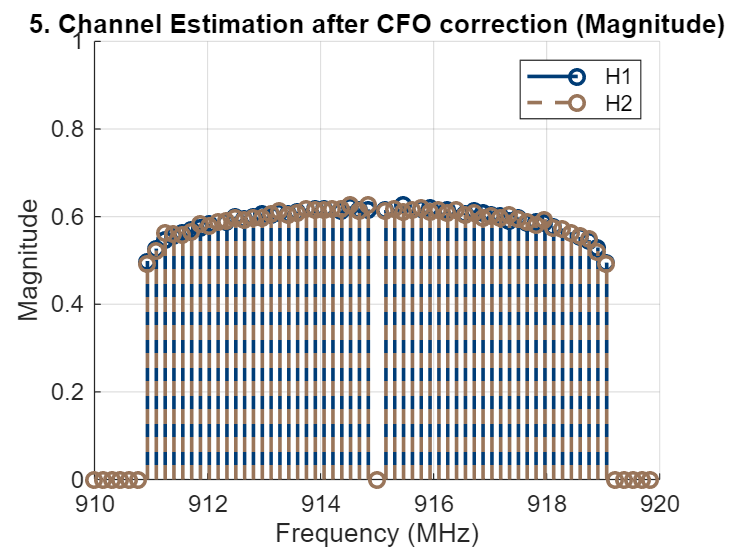

function sig_CFO_corrected = CFO_correction(sig, L, cfo_ppm)
    global ts;
    global fc;
    global fs;

    delta_f= fc*cfo_ppm/1e6;
    
    t = (0:L-1) * ts;
    idx = exp(-1j*2*pi* delta_f .*t);
    sig_CFO_corrected = sig .* idx(:);
end

sig_CFO_corrected = CFO_correction(buffer(sec_beg:sec_end), sec_end-sec_beg+1, cfo_ppm);


H1 = channel_est_LTS(sig_CFO_corrected, lts_start-sec_beg+1);
H2 = channel_est_LTS(sig_CFO_corrected, lts_start-sec_beg+1+64);

% plot magnitude
freq_vector = 915*1e6 + (-64/2:64/2-1) * (fs/64);
close all;
figure(2); hold on;
s1 = stem(freq_vector/1e6, abs(H1), 'Color', '#003C76', 'LineWidth', 1.5);hold on;
s2 = stem(freq_vector/1e6, abs(H2), '--', 'Color', '#99755A', 'LineWidth', 1.5);
xlabel('Frequency (MHz)');
ylabel('Magnitude');
axis([910 920 0 1]);
legend([s1(1), s2(1)],'H1', 'H2');
title('5. Channel Estimation after CFO correction (Magnitude)');
grid on;
hold off;

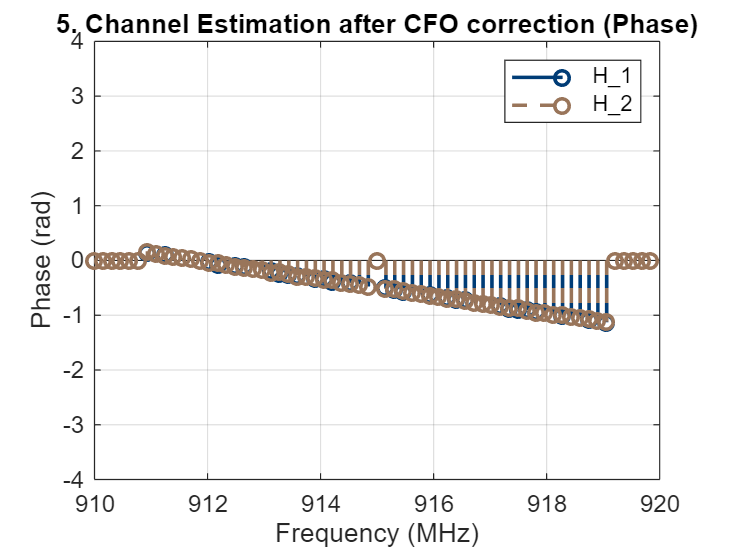


% plot phase
figure(3);
s1 = stem(freq_vector/1e6, angle(H1), 'Color', '#003C76', 'LineWidth', 1.5);hold on;
s2 = stem(freq_vector/1e6, angle(H2), '--', 'Color', '#99755A', 'LineWidth', 1.5);
xlabel('Frequency (MHz)');
ylabel('Phase (rad)');
axis([910 920 -4 4])
legend([s1(1), s2(1)],'H\_1', 'H\_2');
title('5. Channel Estimation after CFO correction (Phase)');
grid on;
hold off;

**Oberservation:**

1. The magnitude pattern of H1 and H2 becomes flatter compared with (1).

2. Their phases match with each other after CFO correction.

**(6) **Use the estimated channel in (5) for equalization. Plot the equalized received constellation of the data tones. What do you observe?

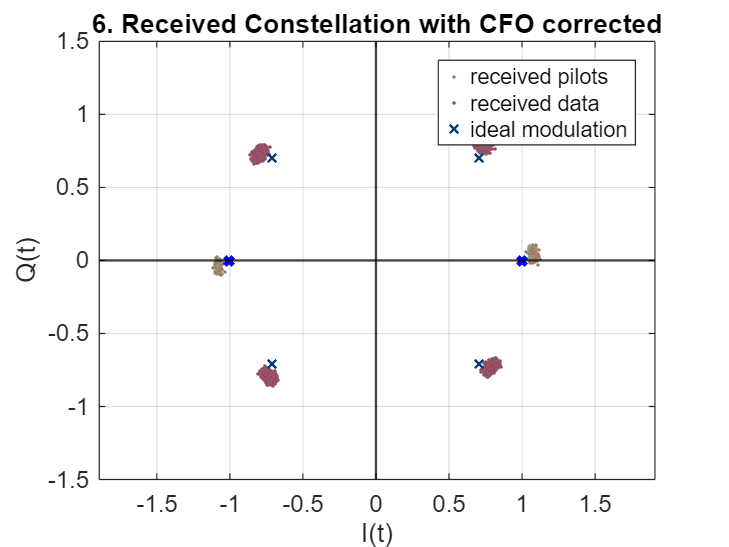

H_est = (H1+H2)/2;
Data_rx = zeros(48*num_of_symbol, 1);
Pilot_rx = zeros(4*num_of_symbol, 1);

P_OFDM = mean(abs (sig_CFO_corrected(ofdm_start-sec_beg+1:ofdm_start + 80*num_of_symbol-1 -sec_beg+1) ) );
for ii = 0:num_of_symbol-1 %!!!!!P_OFDM to be determined
    sig_c = ofdm_removeCP(sig_CFO_corrected(ofdm_start + ii*(N_FFT+N_CP) -sec_beg+1: ofdm_start-1 + (ii+1)*(N_FFT+N_CP) -sec_beg+1));
    X_rx = fftshift(fft(sig_c));
    [Pilot, Data] = Equalize(X_rx, H_est); % H_est = (H1+H2)/2;
    Data_rx(48*ii+1 : 48*(ii+1)) = Data;
    Pilot_rx(4*ii+1 : 4*(ii+1)) = Pilot;
end


I_data = real(Data_rx);
Q_data = imag(Data_rx);
I_pilot = real(Pilot_rx);
Q_pilot = imag(Pilot_rx);

% ideal symbols
M = 4;  % 16-QAM
ideal_symbols = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);
Ii = real(ideal_symbols);
Qi = imag(ideal_symbols);

% plot data and pilot
close all;
figure(1);
plot(I_pilot, Q_pilot, 'o','Color', '#939880', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 
hold on;
plot(I_data, Q_data, 'o', 'Color', '#875B75', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 

% plot ideal symbol
plot(Ii, Qi, 'x', 'Color', '#003C76', 'MarkerSize', 5, 'LineWidth', 1);
I_bpsk = [1, -1];
Q_bpsk = [0, 0];
plot(I_bpsk, Q_bpsk, 'bx', 'MarkerSize', 5, 'LineWidth', 2); 
 

axis([-1.5 1.5 -1.5 1.5]);
xlabel('I(t)');
ylabel('Q(t)');

xline(0, 'k', 'LineWidth', 1); % Real axis (vertical)
yline(0, 'k', 'LineWidth', 1); % Imaginary axis (horizontal)
legend({'received pilots', 'received data', 'ideal modulation'}, 'Location', 'northeast');
title('6. Received Constellation with CFO corrected');

axis equal;
grid on;
hold off;

**Observation:**

By taking CFO correction, the constellation tends to converge around ideal constellation points. Comparing to (2), it is trivially more suitable for demodulation. However, there are still existing offsets between clusters (".") and ideal points ("x"). 

**(7)** Use the four pilot tones to track the residual CFO and correct the data tones accordingly. With the assistance of the pilot tones, plot the received constellation. What do you observe?

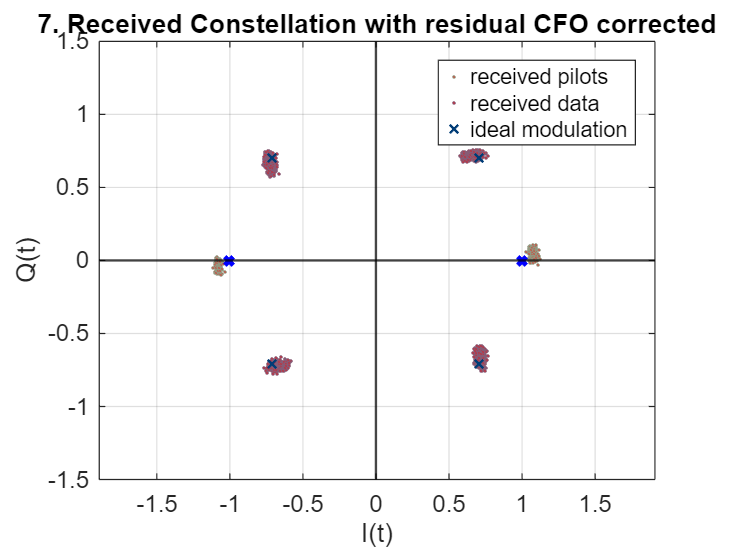

% calculate residual CFO phase　(beta) for one OFDM symbol
function res_CFO_phase = Res_CFO_calc(Pilots, Q)
    res_CFO_phase = angle(sum(Pilots .* conj(Q)));
end

% perform residual CFO correction for one OFDM symbol
function Data_res_CFO_corrected = Res_CFO_correction(Data, res_CFO_phase)
    Data_res_CFO_corrected = Data*exp(-res_CFO_phase);
end

signal_rx = sig_CFO_corrected;
Data_rx = zeros(48*num_of_symbol, 1);
Pilot_rx = zeros(4*num_of_symbol, 1);


for ii = 0:num_of_symbol-1 %!!!!!P_OFDM to be determined
    sig_c = ofdm_removeCP(signal_rx(ofdm_start + ii*(N_FFT+N_CP) -sec_beg+1: ofdm_start-1 + (ii+1)*(N_FFT+N_CP) -sec_beg+1));
    X_rx = fftshift(fft(sig_c));
    [Pilot, Data] = Equalize(X_rx, H_est); % H_est = (H1+H2)/2;

    Q = H_est(pilot_idx); % done by LTS
    res_CFO_phase = Res_CFO_calc(Pilot, Q);
    Data_res_CFO_corrected = Res_CFO_correction(Data, res_CFO_phase);
    Data_rx(48*ii+1 : 48*(ii+1)) = Data_res_CFO_corrected;
    Pilot_rx(4*ii+1 : 4*(ii+1)) = Pilot;
end

I_data = real(Data_rx);
Q_data = imag(Data_rx);
I_pilot = real(Pilot_rx);
Q_pilot = imag(Pilot_rx);

% ideal symbols
M = 4;  % 16-QAM
ideal_symbols = qammod(0:M-1, M, 'gray', 'UnitAveragePower', true);
Ii = real(ideal_symbols);
Qi = imag(ideal_symbols);

% plot data and pilot
close all;
figure(1);
plot(I_pilot, Q_pilot, 'o','Color', '#939880', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 
hold on;
plot(I_data, Q_data, 'o', 'Color', '#875B75', 'MarkerFaceColor', 'r', 'MarkerSize', 1); 

% plot ideal symbol
plot(Ii, Qi, 'x', 'Color', '#003C76', 'MarkerSize', 5, 'LineWidth', 1);
I_bpsk = [1, -1];
Q_bpsk = [0, 0];
plot(I_bpsk, Q_bpsk, 'bx', 'MarkerSize', 5, 'LineWidth', 2); 
 

axis([-1.5 1.5 -1.5 1.5]);
xlabel('I(t)');
ylabel('Q(t)');

xline(0, 'k', 'LineWidth', 1); % Real axis (vertical)
yline(0, 'k', 'LineWidth', 1); % Imaginary axis (horizontal)
legend({'received pilots', 'received data', 'ideal modulation'}, 'Location', 'northeast');
title('7. Received Constellation with residual CFO corrected');

axis equal;
grid on;
hold off;

**Observation:**

By taking CFO correction, the constellation tends to converge around ideal constellation points. Comparing to (2), it is trivially more suitable for demodulation. However, there are still existing offsets between clusters (".") and ideal points ("x"). 

**(8)** Vary (increase) the artificial CFO. Improve your CFO estimation algorithm to the best you can. For the artificial CFO values you tested, plot the true CFO on the x-axis and the estimated CFO on the y-axis. What is the largest CFO that can be corrected using your algorithm?

**(9)** Explain your CFO estimation algorithm in (8).

#### Our Algorithm

- Find the first LTS, $x_1$, and the second LTS, $x_2$. The length of $x_1$ = the length of $x_2$ = $L=64$.

- Compute $P=\sum_1^L x_2 \cdot x_1^*$, and use angle() to get $\hat{\phi} =\angle \;P$. Since the angle() function returns phase angle in $\left\lbrack -\pi ,\pi \right\rbrack$, to extend the usage, we add the value of angle by $2\pi$ if the value < 0.

- CFO in ppm $=\frac{\hat{\phi} }{2\pi {\mathrm{LT}}_s }\cdot \frac{1}{f_c \cdot {10}^6 }$

#### Limitation of Our Algorithm (largest acceptable CFO)

Theoretically, since we are taking $\arctan \left(\frac{I\left\lbrace P\left(k\right)\right\rbrace }{R\left\lbrace P\left(k\right)\right\rbrace }\right)$, it is required that the angle of P is smaller than $2\pi$. The critical point happens when $\frac{2\pi \;\Delta f\;L}{f_s }=2\pi \Rightarrow \Delta f=\frac{f_s }{4L}\Rightarrow \mathrm{PPM}=\frac{\Delta f\cdot {10}^6 }{f_c }=\frac{f_s \cdot {10}^6 }{L\cdot f_c }=170\ldotp 77$

According to our experiment figure, it is also shown that the CFO can be correctly estimated up to 170 ppm.

% using 'sig_100' in (1), please load 'single_100.mat'
% using 'ts', 'fc', please load the 'Wifi-Modulation Initialize' section 

% add CFOs
CFOs = {40, 80, 120, 140, 160, 170, 180, 200};
info = struct('CFO_true', CFOs);

function tx_sig_CFO = TX_CFO_PPM(sig, L, PPM)
    global ts; % ts = 1/fs
    global fc;
    delta_f= fc*PPM/1e6;
    
    t = (0:L-1) * ts;
    idx = exp(1j*2*pi* delta_f .*t);
    tx_sig_CFO = sig .* idx(:);
end


tx_sig_100_CFOs = zeros(length(sig_100), length(CFOs));
for ii = 1:length(CFOs)
    tx_sig_100_CFOs(:, ii) = TX_CFO_PPM(sig_100, length(sig_100), info(ii).CFO_true);
end

Transmit & receive

function buffers_CFO = send_multi_frame(tx_sig_100_CFOs, send_amp)
    addpath("./test_code/");
    
    l = height(tx_sig_100_CFOs) + 200;
    [radio_Tx,radio_Rx] = USRP_init(l);
    buffers_CFO = zeros(5*l, width(tx_sig_100_CFOs));
    
    % Transmit the frame we generate
    for k = 1:width(tx_sig_100_CFOs)
        padded_sig_100 = send_amp*[zeros(100, 1); tx_sig_100_CFOs(:, k); zeros(100, 1)];
        buffer_CFO = zeros(5*l, 1);
        for ii = 1:3
            if ii == 2
                tunderrun = radio_Tx(padded_sig_100);
            else
                tunderrun = radio_Tx(complex(zeros(l, 1)));
            end
            [rcvdSignal, ~, toverflow] = step(radio_Rx);
            buffer_CFO((1+(ii-1)*l):(ii*l)) = rcvdSignal;
        end
        % Keep reception for 2 frames
        for ii = 4:5
            [rcvdSignal, ~, toverflow] = step(radio_Rx);
            buffer((1+(ii-1)*l):(ii*l)) = rcvdSignal;
        end 
        buffers_CFO(:, k) = buffer_CFO;
    end
    
    release(radio_Tx)
    release(radio_Rx)
end


buffers_CFO = zeros((length(sig_100)+200)*5, length(CFOs));
if RE_RECEIVE_DIFFERENT_CFO == 1
    buffers_CFO = send_multi_frame(tx_sig_100_CFOs, send_amp);
else
    load('different_CFOs.mat')
end

Trim & find starts

function [sec_beg, sec_end] = fast_trim(buffer, plot_len, sec_blank)
    crt = 0.01;
    sec_beg = sec_blank;
    for ii = 1:length(buffer)
        if buffer(ii)>crt
            sec_beg = ii;
            break
        end
    end
    sec_beg = sec_beg - sec_blank + 1;
    sec_end = sec_beg + plot_len + 2*sec_blank;
end

plot_len = length(sig_100); 
sec_blank = 200; 
for ii=1:length(CFOs)
    [sec_beg, sec_end] = fast_trim(buffers_CFO(:, ii), plot_len, sec_blank);
    [lts_start, ofdm_start] = LTS_CONV(buffers_CFO(sec_beg:sec_end, ii), sec_beg, single_LTS);
    % figure;
    % plot(real(buffers_CFO(sec_beg:sec_end, ii)));
    info(ii).sec_beg = sec_beg;
    info(ii).sec_end = sec_end;
    info(ii).lts_start = lts_start;
    info(ii).ofdm_start = ofdm_start;
end

Find CFOs

function cfo_ppm = get_CFO_ppm(lts_start, buffer, ts, fc)
    lts_start_1 = lts_start;
    lts_start_2 = lts_start_1 + 64;
    lts_1 = buffer(lts_start_1:lts_start_1 + 64-1);
    lts_2 = buffer(lts_start_2:lts_start_2 + 64-1);

    phase_diff = angle(sum(lts_2 .* conj(lts_1)));
    % if phase < 0, add 2pi
    if phase_diff < 0
        phase_diff = phase_diff + 2*pi;
    end
    cfo_hz = phase_diff / (2*pi*64*ts);
    cfo_ppm = cfo_hz / fc * 1e6;
end

for ii=1:length(CFOs)
    info(ii).CFO_est = get_CFO_ppm(info(ii).lts_start, buffers_CFO(:,ii), ts, fc);
end

Plot estimated CFO (y) v.s. true CFO (x)

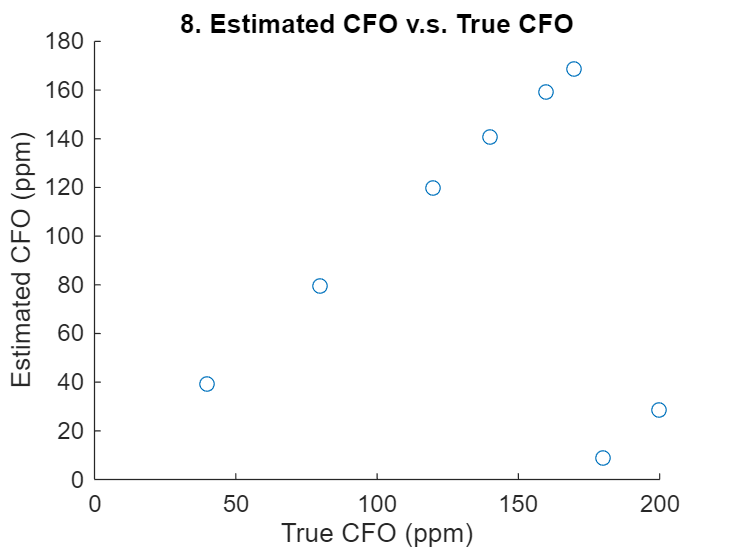

figure;
scatter([info.CFO_true], [info.CFO_est]);
xlabel('True CFO (ppm)')

ylabel('Estimated CFO (ppm)')
title('8. Estimated CFO v.s. True CFO');